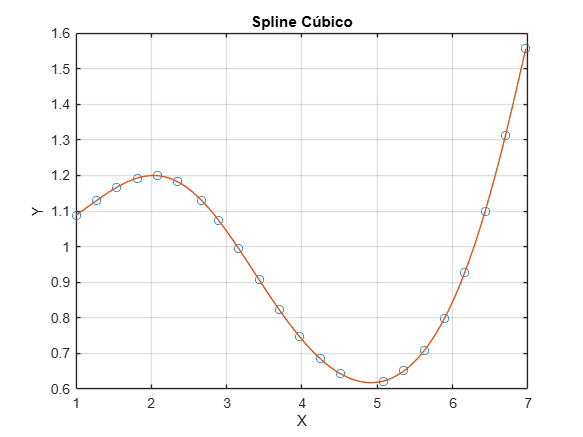

clear all
%PUNTO 1
%n=22
X = [1, 1.27, 1.54, 1.81, 2.08, 2.35, 2.67, 2.89, 3.16, 3.43, 3.7, 3.97, 4.24, 4.51, 5.08, 5.35, 5.62, 5.89, 6.16, 6.43, 6.7, 6.97];
Y = exp(X .* sin(X) / 10);
n = length(X);

a0 = 0;
an = 0; 

h = diff(X);

A = zeros(n);
b = zeros(n, 1);

A(1,1) = 1;
A(n,n) = 1;
b(1) = a0;
b(n) = an;

for i = 2:n-1
    A(i, i-1) = h(i-1);
    A(i, i) = 2 * (h(i-1) + h(i));
    A(i, i+1) = h(i);
    b(i) = 3 * ((Y(i+1) - Y(i)) / h(i) - (Y(i) - Y(i-1)) / h(i-1));
end

M = A \ b;

a = Y(1:end-1);
b = zeros(n-1, 1);
c = M(1:end-1);
d = zeros(n-1, 1);

for i = 1:n-1
    b(i) = (Y(i+1) - Y(i)) / h(i) - h(i) * (2 * M(i) + M(i+1)) / 3;
    d(i) = (M(i+1) - M(i)) / (3 * h(i));
end

spline_piece = cell(1, n-1);

for i = 1:n-1
    spline_piece{i} = @(x) (x >= X(i) & x <= X(i+1)) .* (a(i) + b(i) .* (x - X(i)) + c(i) .* (x - X(i)).^2 + d(i) .* (x - X(i)).^3);
end

spline = @(x) sum(cellfun(@(f) f(x), spline_piece));

xx = linspace(min(X), max(X), 1000);
yy = arrayfun(spline, xx);

figure;
plot(X, Y, 'o', xx, yy, '-');
title('Spline Cúbico');
xlabel('X');
ylabel('Y');
grid on;

% Calcular la integral de la función spline utilizando la regla del trapecio
integral_S = 0; % Inicializar la integral de la función spline

for i = 1:n-1
    % Calcular el área bajo el segmento de spline actual usando la regla del trapecio
    h_i = X(i+1) - X(i); % Ancho del segmento
    integral_S = integral_S + (h_i / 2) * (spline(X(i)) + spline(X(i+1)));
end

disp(['Integral de f(x): ', num2str(integral_S)]);

Integral de f(x): 10.9944


disp(['Integral de S(x): ', num2str(integral_S)]);

Integral de S(x): 10.9944
